# Questão 2

Valores do sistema a partir da equação diferença  para entrada degrau

u = ones(100, 1);
y = zeros(100, 1);

y(1:2) = 0;
for k=3:length(u)
    y(k) = 1.881 * y(k-1) - 0.9048 * y(k-2) ...
        + 0.01207 * u(k-1) + 0.01167 * u(k-2);
end

## EMQ ordem 1

[theta1, estimative1] = LS(1, 1, y, u);
residues1 = y - estimative1;

## EMQ ordem 2

[theta2, estimative2] = LS(2, 2, y, u);
residues2 = y - estimative2;

## EMQ ordem 3

[theta3, estimative3] = LS(3, 3, y, u);
residues3 = y - estimative3;

## EMQ ordem 4

[theta4, estimative4] = LS(4, 4, y, u);
residues4 = y - estimative4;

## EMQ ordem 5

[theta5, estimative5] = LS(5, 5, y, u);
residues5 = y - estimative5;

## Resultados dos resíduos

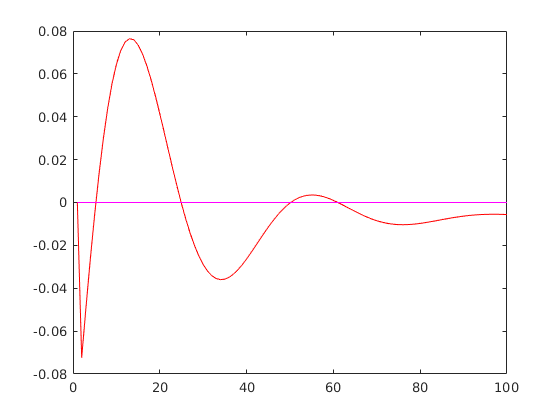

plot(1:100, residues1, 'r');
hold on
plot(1:100, residues2, 'b');
plot(1:100, residues3, 'y');
plot(1:100, residues4, 'g');
plot(1:100, residues5, 'm');
hold off

## Adicionando erro dinâmico e erro interno do sensor

theta = zeros(6, 100);

for k = 1:100
    %e_d = 0.5*randn(100, 1);
    e_d = normrnd(0, .05, 100, 1);
    
    u = ones(100, 1);
    y = zeros(100, 1);
    
    y(1:2) = 0;
    for k=3:length(u)
        y(k) = 1.881 * y(k-1) - 0.9048 * y(k-2) ...
            + 0.01207 * u(k-1) + 0.01167 * u(k-2) + e_d(k);
    end
    e_s = normrnd(0, .05, 100, 1);
    y = y + e_s;
    LS(3, 3, y, u);
end